## Load scene data files

load data from Driving Scenario Designer

load COMTraj.mat

## Define reference points

xRef = xCOM;
yRef = yCOM;
refPose = [xRef yRef];

## Define vehicle parameters 

X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

## Calculating reference pose vectors

**Based on how far the vehicle travels, the pose is generated using 1-D lookup tables.**

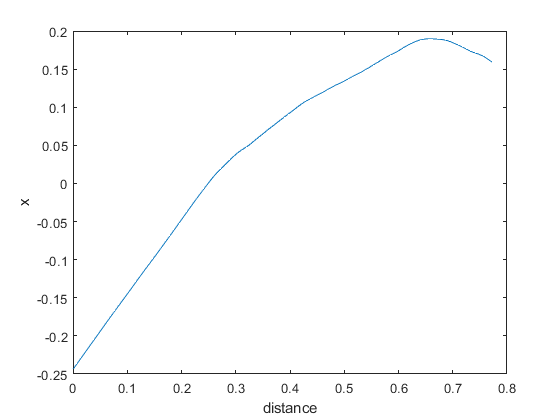

% calculate distance vector
distancematrix = squareform(pdist(refPose));
distancesteps = zeros(length(refPose)-1,1);
for i = 2:length(refPose)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,100); % Linearize distance

% linearize X and Y vectors based on distance
xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
xRef2s = smooth(gradbp,xRef2); % smooth waypoints
yRef2s = smooth(gradbp,yRef2); % smooth waypoints
save VehiclePath xRef2s yRef2s totalDistance
plot(gradbp,xRef2s)
xlabel('distance')
ylabel('x')

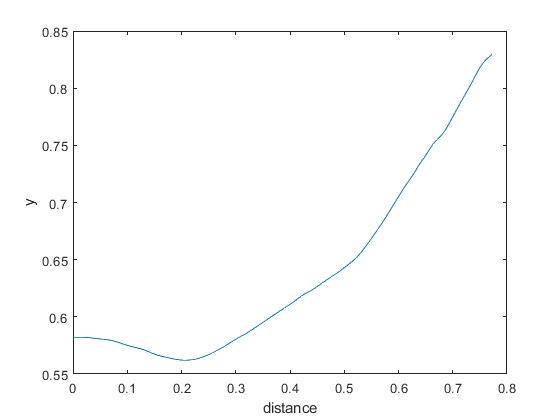

plot(gradbp,yRef2s)
xlabel('distance')
ylabel('y')

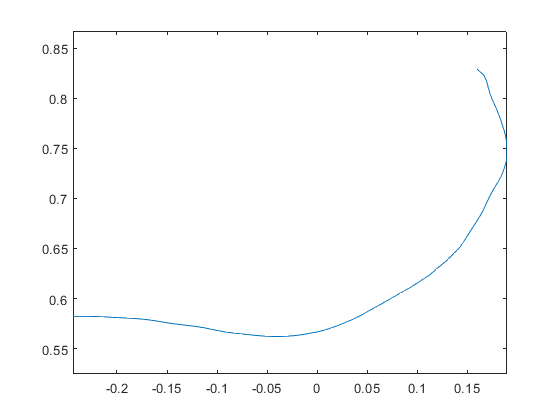

plot(xRef2s,yRef2s), axis equal

## Calculate theta vector

**theta = orientation angle of the path at reference points **

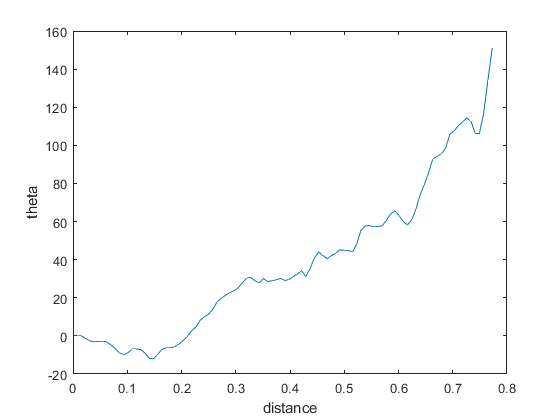

thetaRef = zeros(length(gradbp),1);
for i = 2:length(gradbp)
    thetaRef(i,1) = atan2d((yRef2(i)-yRef2(i-1)),(xRef2(i)-xRef2(i-1)));
end
thetaRefs = smooth(gradbp,thetaRef); % smooth of theta
psi_o = thetaRefs(1)*(pi/180); % initial yaw angle
plot(gradbp,thetaRefs)
xlabel('distance')
ylabel('theta')

## Create direction vector

direction = ones(length(gradbp),1);

## Calculate curvature vector

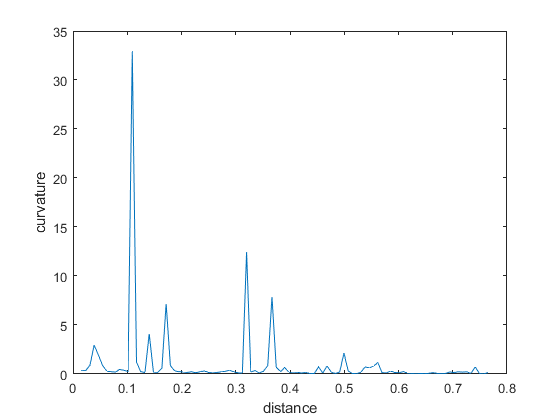

coors_xy = [xRef2s,yRef2s];
[~,curve] = curvature(coors_xy);
figure
plot(gradbp,curve)
xlabel('distance')
ylabel('curvature')